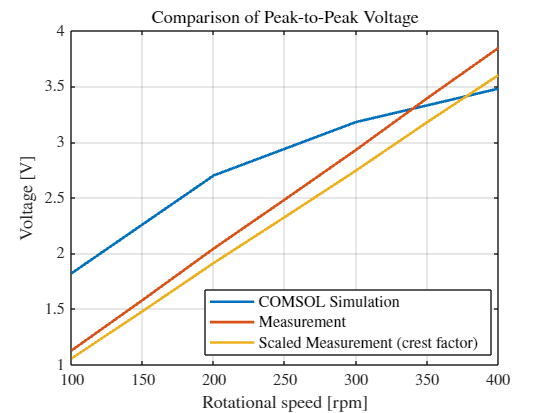

%% Voltage Comparison: COMSOL Simulation vs Measurement vs Scaled Measurement
% Script to compare:
%   - Voltage 1: results from COMSOL simulation
%   - Voltage 2: experimentally measured voltage
%   - Voltage 3: measured voltage, scaled by the crest factor
% as a function of rotational speed (RPM)

clear; clc; close all;

%% COMSOL simulation data - Voltage 1
rpm_sim = [100 200 300 400];
V_sim   = [1.82 2.7 3.18 3.48];

%% Measured data - Voltage 2
rpm_meas = [100 150 200 250 300 350 400];
V_meas   = [1.126 1.580 2.043 2.484 2.930 3.394 3.845];

%% Parameter: Crest Factor
% Set here the known/measured crest factor value.
% For a pure sinusoidal waveform crest_factor = sqrt(2) ~= 1.414
crest_factor = 1.51;   % <-- CHANGE to the correct value

%% Compute Voltage 3 - Measurement scaled by the crest factor
V_meas_scaled = V_meas .* sqrt(2) ./ crest_factor;
rpm_meas_scaled = rpm_meas;   % same RPM base as the measurement

%% Comparison plot
figure('Color','w');
hold on;

plot(rpm_sim, V_sim, '-', 'LineWidth', 1.8, 'DisplayName', 'COMSOL Simulation');

plot(rpm_meas, V_meas, '-', 'LineWidth', 1.8, 'DisplayName', 'Measurement');

plot(rpm_meas_scaled, V_meas_scaled, '-', 'LineWidth', 1.8, 'DisplayName', 'Scaled Measurement (crest factor)');

hold off;
grid on;
box on;

xlabel('Rotational speed [rpm]', 'Interpreter', 'latex', 'FontSize', 12);
ylabel('Voltage [V]', 'Interpreter', 'latex', 'FontSize', 12);
title('Comparison of Peak-to-Peak Voltage', 'Interpreter', 'latex', 'FontSize', 13);
legend('Interpreter', 'latex', 'Location', 'best', 'FontSize', 11);

set(gca, 'FontSize', 11, 'TickLabelInterpreter', 'latex');
xlim([100 400]);

%% Export plot as PDF (publication quality)
exportgraphics(gcf, 'voltage_comparison.pdf', 'ContentType', 'vector', 'Resolution', 300);


fprintf('Plot exported as voltage_comparison.pdf\n');

Plot exported as voltage_comparison.pdf
